clc
clear
load("MatlabData\trainingData_OG.mat")
load("MatlabData\ValidationData_OG.mat")

Removing features

trainingData(:,14) = [];
trainingData(:,9) = [];
trainingData(:,7) = [];
trainingData(:,2) = [];
trainingData(:,1) = [];
ValidationData(:,14) = [];
ValidationData(:,9) = [];
ValidationData(:,7) = [];
ValidationData(:,2) = [];
ValidationData(:,1) = [];

Reducing the data with LDA to 6 dimensions

W_LDA = LDA_Train(trainingData, trainingLabel,6,length(trainingData)/21);
trainingData_LDA = (W_LDA.' * trainingData.').';
ValidationData_LDA = (W_LDA.' * ValidationData.').';

Normalising the data

[normalizedData_LDA,centerValue_LDA,scaleValue_LDA] = normalize(trainingData_LDA,"center",...
    "scale");
trainingData_LDA = normalizedData_LDA;
ValidationData_LDA = (ValidationData_LDA - centerValue_LDA) ./ scaleValue_LDA;


## Line-search

n = 100;
TP = zeros(1,n);
FN = zeros(1,n);
% gamma = linspace(0.0005,0.05,n);
gamma = linspace(0.01,0.00001,n);

boxconstraint = 1.0e+03 *

    0.5000    0.5101    0.5202    0.5303    0.5404    0.5505    0.5606    0.5707    0.5808    0.5909    0.6010    0.6111    0.6212    0.6313    0.6414    0.6515    0.6616    0.6717    0.6818    0.6919    0.7020    0.7121    0.7222    0.7323    0.7424    0.7525    0.7626    0.7727    0.7828    0.7929    0.8030    0.8131    0.8232    0.8333    0.8434    0.8535    0.8636    0.8737    0.8838    0.8939    0.9040    0.9141    0.9242    0.9343    0.9444    0.9545    0.9646    0.9747    0.9848    0.9949


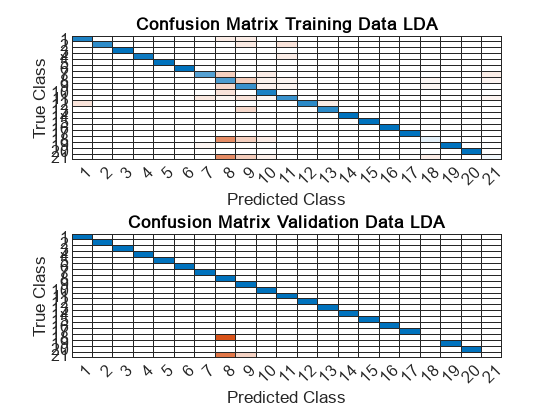

f = waitbar(0, 'Starting');
for i=1:n
    t = templateSVM('KernelFunction','rbf','KernelScale', 1/(sqrt(gamma(i))),'BoxConstraint',1000);
    subplot(2,1,1)
    SVMModel = fitcecoc(trainingData_LDA,trainingLabel,"Learners",t,"Coding","onevsone");
    predictedLabel = predict(SVMModel, trainingData_LDA);
    % Accuracy(predictedLabel,trainingLabel.')
    acc(i,1) = Accuracy(predictedLabel,trainingLabel.');
    cm = confusionchart(trainingLabel, predictedLabel);
    cm.Normalization = "row-normalized";
    cm.Title = 'Confusion Matrix Training Data LDA';
    subplot(2,1,2)
    predictedLabel = predict(SVMModel, ValidationData_LDA);
    % Accuracy(predictedLabel,validationLabel.')
    cm = confusionchart(validationLabel, predictedLabel);
    cm.Normalization = "row-normalized";
    cm.Title = 'Confusion Matrix Validation Data LDA';
    acc(i,2) = Accuracy(predictedLabel,validationLabel.');
    TP(i) = cm.NormalizedValues(21,21);
    FN(i) = sum(cm.NormalizedValues(:,21)) - TP(i);
    waitbar(i/n, f, sprintf('Progress: %d %%', floor(i/n*100)));
end

close(f)

## Plotting

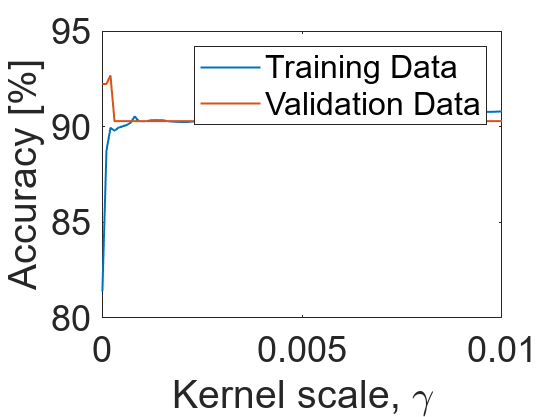

figure()
plot(gamma, acc(:,1).*100,gamma, acc(:,2).*100, LineWidth=1)
xlabel("Kernel scale, \gamma")
ylabel("Accuracy [%]")
legend("Training Data", "Validation Data")
set(gca,'FontSize',18)
saveas(gcf,'Improvements/Images/LineSearch-Acc','epsc')

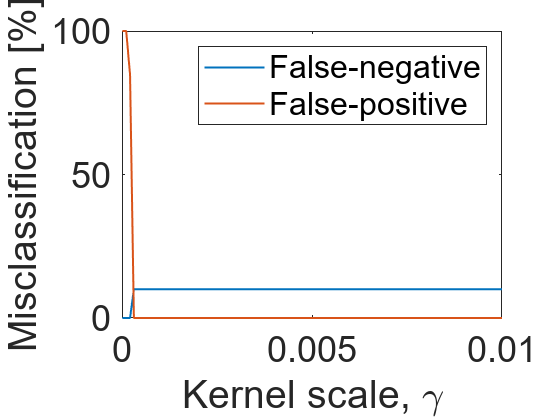


figure()
plot(gamma,FN/20.*100,gamma,(1-TP).*100, LineWidth=1)
xlabel("Kernel scale, \gamma")
ylabel("Misclassification [%]")
legend("False-negative", "False-positive")
set(gca,'FontSize',18)
saveas(gcf,'Improvements/Images/LineSearch-Misclassification','epsc')

function W = LDA_Train(data, label, D, Nk)
    % Calculate mean of each class
    for i=1:21
        mu(i,:)= mean(data(label == i,:));
    end
    % Calculate total mean
    mu(22,:) = mean(data);

    % Calculate within-class scattesr
    Sw = 0;
    for j=1:size(mu,1)-1
        Sw = Sw + (data(find(label==j),:)' - mu(j,:)') * (data(find(label==j),:)' - mu(j,:)')';
    end
    % Calculate between-class scatter
    Sb = Nk .* (mu(1:21,:)' - mu(22,:)') * (mu(1:21,:)' - mu(22,:)')';

    % Use the eigenvalue decomposition and sort it in decending order
    [V e] = eig(Sb,Sw);
    [B,I] = sort(diag(e),'descend');

    % Take D number of eigenvectores corresponding to the largest values
    for i=1:D
        W(:,i) = V(:,I(i));
    end
end
function acc = Accuracy(predicted, true)
    [Ntst sz]= size(predicted);
    % Number of correct classifications
    correct = sum(predicted == true);
    % Accuracy
    acc = correct/Ntst;
end